% Define the inputs
current_stock_price = 100; % in dollars
earnings_per_share = 5;
book_value_per_share = 50;
current_ratio = 2;
debt_to_equity_ratio = 0.5;
expected_rate_of_return = 0.10; % in decimal
forecast_horizon = 1; % in years
average_annual_growth_rate = 0.05; % in decimal
risk_free_rate = 0.02; % in decimal
market_risk_premium = 0.05; % in decimal
tax_rate = 0.25; % in decimal
strike_price = current_stock_price * 1.1; % in dollars
time_to_maturity = 0.5; % in years
implied_volatility = 0.3; % in decimal

% Define the simulation parameters
num_simulations = 10000;
num_steps = 252 * forecast_horizon;
dt = time_to_maturity / num_steps;

% Calculate the earnings yield and return on equity
earnings_yield = earnings_per_share / current_stock_price;
return_on_equity = earnings_per_share / book_value_per_share;

% Calculate the price-to-earnings ratio and price-to-book ratio
price_to_earnings = 1 / earnings_yield;
price_to_book = current_stock_price / book_value_per_share;

% Calculate the weighted average of the price-to-earnings ratio and price-to-book ratio
weighted_average_ratio = (price_to_earnings * return_on_equity + price_to_book) / (return_on_equity + 1);

% Calculate the expected earnings per share for the forecast horizon
expected_earnings_per_share = earnings_per_share * (1 + average_annual_growth_rate)^forecast_horizon;

% Calculate the expected stock price at the end of the forecast horizon using the Gordon Growth Model
expected_stock_price = (expected_earnings_per_share * (1 + earnings_yield)) / (expected_rate_of_return - average_annual_growth_rate);

% Calculate the beta of the company's stock using the Capital Asset Pricing Model
beta = 1 + (debt_to_equity_ratio * (1 - tax_rate));
cost_of_equity = risk_free_rate + beta * market_risk_premium;

% Calculate the expected rate of return for the company's stock
expected_rate_of_return = cost_of_equity * (1 - tax_rate);

% Calculate the intrinsic value of the stock using the discounted cash flow model
discount_factor = 1 / (1 + expected_rate_of_return)^forecast_horizon;
intrinsic_value = (expected_earnings_per_share * discount_factor + book_value_per_share * discount_factor) / (1 + discount_factor);

% Run Monte Carlo simulation to model future stock prices
% Define the drift and volatility terms
drift = (expected_rate_of_return - 0.5 * implied_volatility^2) * dt;
volatility = implied_volatility * sqrt(dt);

% Generate the stock price paths
stock_price_paths = zeros(num_simulations, num_steps);
stock_price_paths(:,1) = current_stock_price;

for i = 1:num_simulations
    for j = 2:num_steps
        stock_price_paths(i,j) = stock_price_paths(i,j-1) * exp(drift + volatility * randn);
    end
end

% Calculate the option price using the Black-Scholes model
d1 = (log(current_stock_price/strike_price) + (expected_rate_of_return + 0.5 * implied_volatility^2) * time_to_maturity) / (implied_volatility * sqrt(time_to_maturity));
% Calculate d2
d2 = d1 - implied_volatility * sqrt(time_to_maturity);

% Calculate the option price using the Black-Scholes formula
option_price = current_stock_price * normcdf(d1) - strike_price * exp(-expected_rate_of_return*time_to_maturity) * normcdf(d2);

% Display the calculated values
fprintf("Earnings Yield: %f\n", earnings_yield);

Earnings Yield: 0.050000


fprintf("Return on Equity: %f\n", return_on_equity);

Return on Equity: 0.100000


fprintf("Price-to-Earnings Ratio: %f\n", price_to_earnings);

Price-to-Earnings Ratio: 20.000000


fprintf("Price-to-Book Ratio: %f\n", price_to_book);

Price-to-Book Ratio: 2.000000


fprintf("Weighted Average Ratio: %f\n", weighted_average_ratio);

Weighted Average Ratio: 3.636364


fprintf("Expected Earnings per Share: %f\n", expected_earnings_per_share);

Expected Earnings per Share: 5.250000


fprintf("Expected Stock Price: %f\n", expected_stock_price);

Expected Stock Price: 110.250000


fprintf("Intrinsic Value: %f\n", intrinsic_value);

Intrinsic Value: 26.735219


fprintf("Option Price: %f\n", option_price);

Option Price: 5.886128


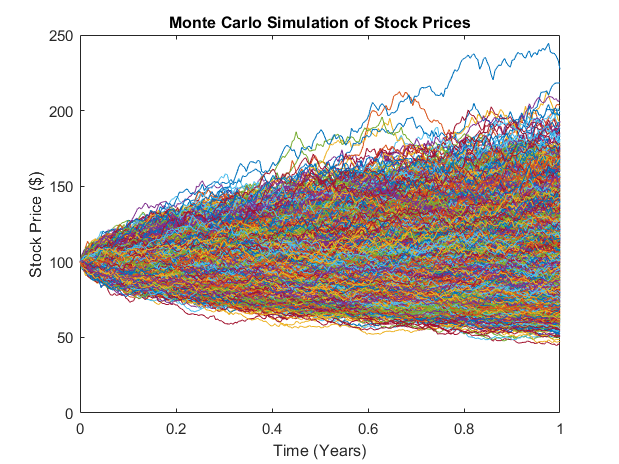


% Plot the stock price paths
figure;
plot(linspace(0, forecast_horizon, num_steps), stock_price_paths');
title('Monte Carlo Simulation of Stock Prices');
xlabel('Time (Years)');
ylabel('Stock Price ($)');

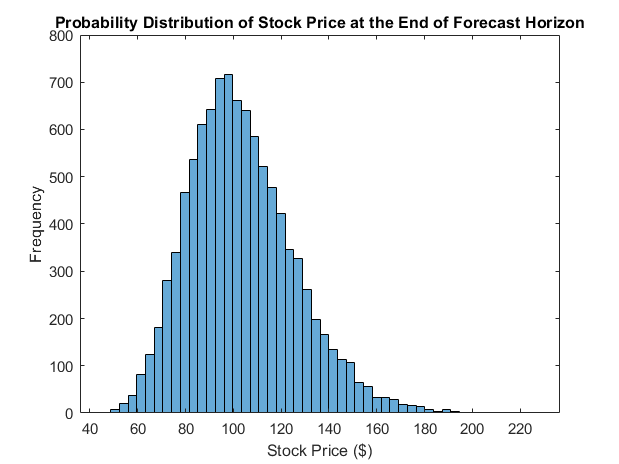


% Plot the probability distribution of the stock price at the end of the forecast horizon
figure;
histogram(stock_price_paths(:,end), 50);
title('Probability Distribution of Stock Price at the End of Forecast Horizon');
xlabel('Stock Price ($)');
ylabel('Frequency');